%audio recording
myvoice=audiorecorder(8000,24,1); 
disp('Start to speak')

Start to speak


recordblocking(myvoice,3) 
disp('End of recording')

End of recording


play(myvoice) 

ans =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 24
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 257
     TotalSamples: 24000
          Running: 'on'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


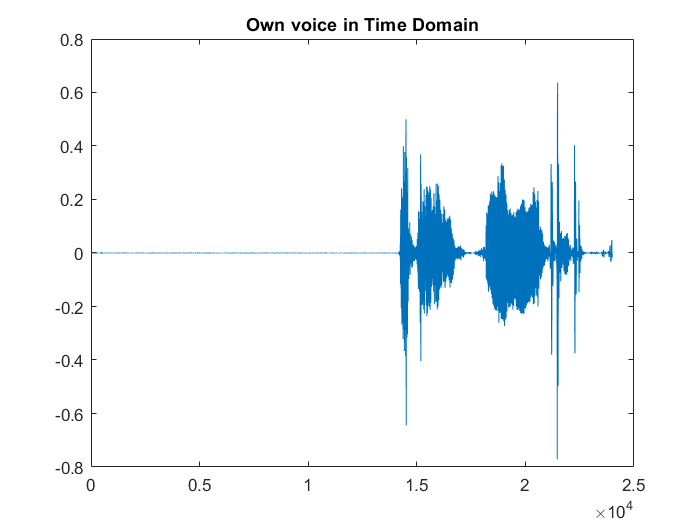

voice_vector=getaudiodata(myvoice);

figure(1)
plot(voice_vector)
title('Own voice in Time Domain');

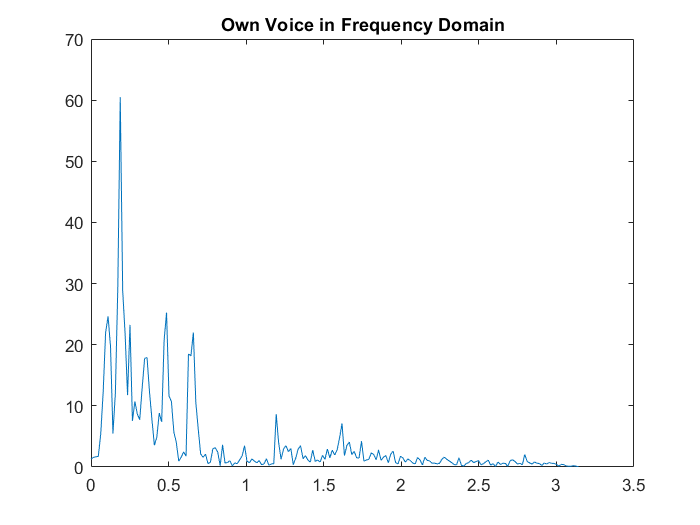

%x = fft(voice_vector);
%figure(2)
%plot(x)

w=0:pi/200:pi;
[h w]=freqz(voice_vector,1,w);
figure(2)
plot(w,abs(h))
title('Own Voice in Frequency Domain')


with_noise1=awgn(voice_vector,99); 
snr = 99  

snr = 99

with_noise2=awgn(voice_vector,20); 
snr = 20  

snr = 20

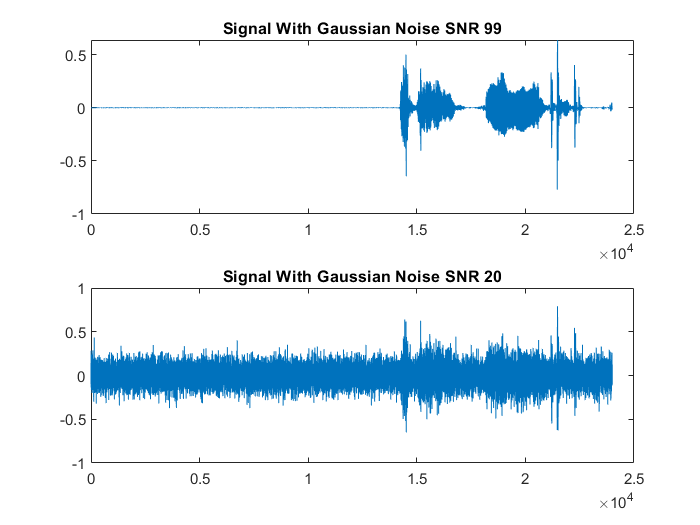


figure(3)
subplot(211)
plot(with_noise1)
title('Signal With Gaussian Noise SNR 99')
subplot(212)
plot(with_noise2)
title('Signal With Gaussian Noise SNR 20')

%low pass filter
F1=8000; 
F2=800;
F3=1000; 
r1=2;  
r2=60; 
p1=1-10.^(-r1/20);  
s1=10.^(-r2/20);    
FF=[F2 F3]; 
ma=[1 0]; 
28

ans = 28

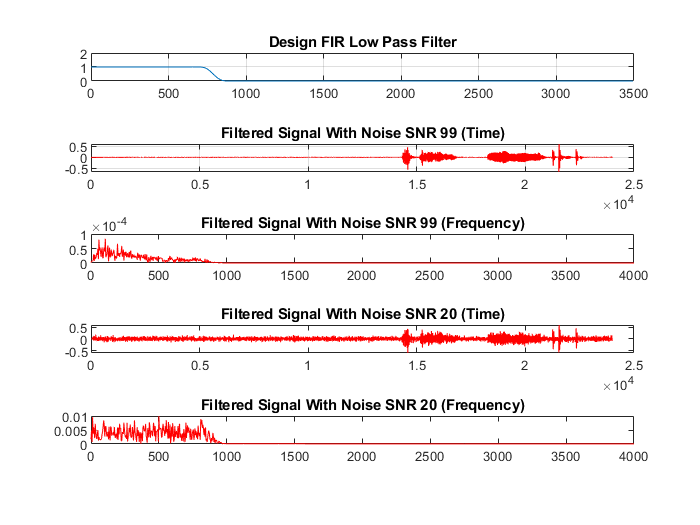

v=[p1 s1];

[A21,wA21,bt,Yp]=kaiserord(FF,ma,v,F1);
lowpassfilter=fir1(A21,wA21,kaiser(A21+1,bt));

[h,w]=freqz(lowpassfilter,1);
figure(4);
subplot(511)
plot(w*7000*0.5/pi,abs(h));
ylim([0,2])
title('Design FIR Low Pass Filter','fontweight','bold');grid;

Signal_1=fftfilt(lowpassfilter,with_noise1);
sound(Signal_1,F1);
sound(Signal_1);
subplot(512)
plot(Signal_1,'r')
title('Filtered Signal With Noise SNR 99 (Time)');
grid;

L = 2000;
NFFT = 2^nextpow2(L); 
signal1=abs(fft(Signal_1,NFFT))/L;
f = F1/2*linspace(0,1,NFFT/2+1);

subplot(513)
plot(f,2*abs(signal1(1:NFFT/2+1)),'r');
title('Filtered Signal With Noise SNR 99 (Frequency)');
Signal_2=fftfilt(lowpassfilter,with_noise2);
sound(Signal_2,F1);
sound(Signal_2);

subplot(514)
plot(Signal_2,'r')
title('Filtered Signal With Noise SNR 20 (Time)');
signal2=abs(fft(Signal_2,NFFT))/L;

subplot(515)
plot(f,2*abs(signal2(1:NFFT/2+1)),'r');
title('Filtered Signal With Noise SNR 20 (Frequency)');

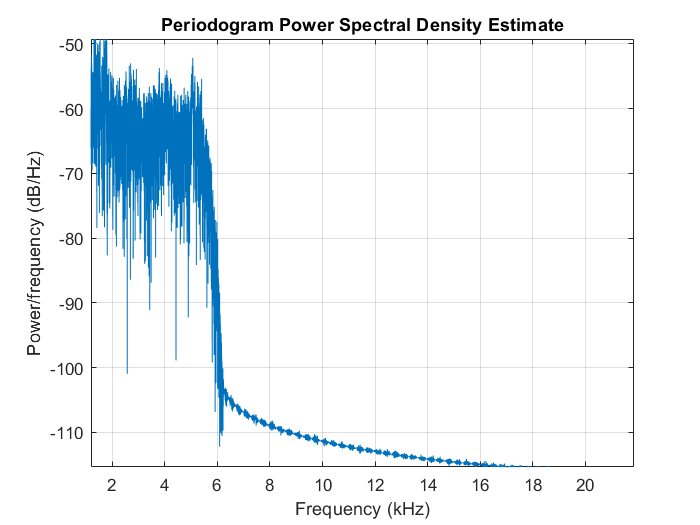


figure
x=Signal_2;
periodogram(gather(x),rectwin(length(x)),length(x),50e3)

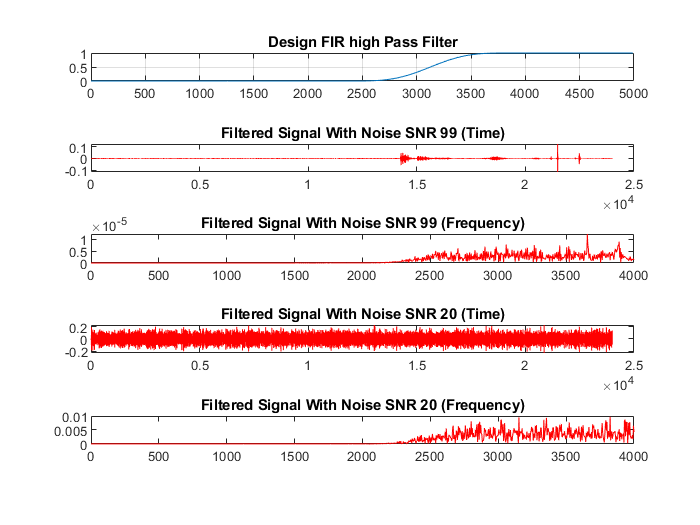

%high pass filter
F1=8000;
F2=3000;
F3=2000;
r1=2;
r2=60;
p=1-10.^(-r1/20);
s=10.^(-r2/20);
FF=[F3 F2];
ma=[1 0];
v=[p s];
[A23,wA23,bt,Yp]=kaiserord(FF,ma,v,F1);
highpassfilter=fir1(A23,wA23,'high',kaiser(A23+1,bt));
[h,w]=freqz(highpassfilter,1);
figure(5);
subplot(511)
plot(w*10000*0.5/pi,abs(h));
title('Design FIR high Pass Filter','fontweight','bold');
grid;
Signal_3=fftfilt(highpassfilter,with_noise1);
sound(Signal_3,F1);
sound(Signal_3);
subplot(512)
plot(Signal_3,'r')
title('Filtered Signal With Noise SNR 99 (Time)');
Signal3=abs(fft(Signal_3,NFFT))/L;
subplot(513)
plot(f,2*abs(Signal3(1:NFFT/2+1)),'r')
title('Filtered Signal With Noise SNR 99 (Frequency)');
Signal_4=fftfilt(highpassfilter,with_noise2);
subplot(514)
plot(Signal_4,'r')
title('Filtered Signal With Noise SNR 20 (Time)');
sound(Signal_4,F1);
sound(Signal_4);
signal4=abs(fft(Signal_4,NFFT))/L;

subplot(515)
plot(f,2*abs(signal4(1:NFFT/2+1)),'r')
title('Filtered Signal With Noise SNR 20 (Frequency)');


figure
y=Signal_3

y =    -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


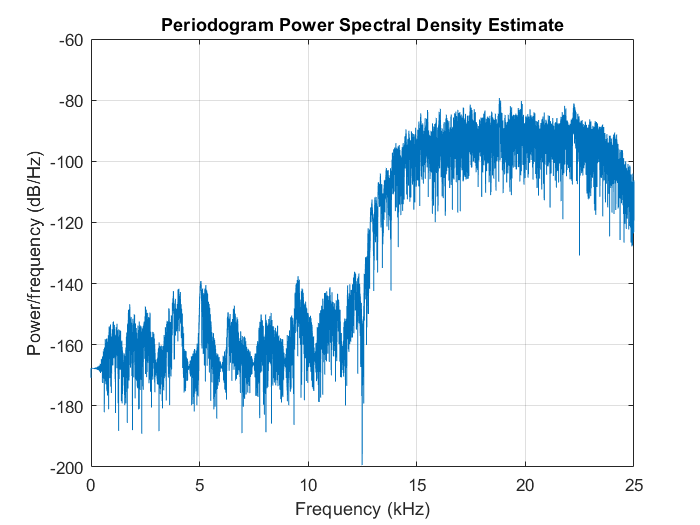

periodogram(gather(y),rectwin(length(y)),length(y),50e3)

%band pass filter
F1=8000;
F=[1000 1300 2210 2410]

F =         1000        1300        2210        2410


ma=[0 1 0];
devs=[0.01 0.05 0.01];
[n,wA23,bt,Yp]=kaiserord(F,ma,devs,F1);
n=n+rem(n,2)

n = 90

bandpassfilter=fir1(n,wA23,'bandpass',kaiser(n+1,bt),'noscale');
[h,w]=freqz(bandpassfilter,1,1024,F1);
figure(6)
subplot(511)
plot(w*10000*0.5/pi,abs(h));
title('DESIGN FIR BAND PASS FILTER','fontWeight','bold');
grid;
signal_5=fftfilt(bandpassfilter,with_noise1)

signal_5 =     0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


sound(signal_5,F1);
sound(signal_5);
subplot(512)
plot(signal_5,'r')
title('Filtered Signal With Noise SNR 99 (Time)');
signal_5=abs(fft(signal_5,NFFT))/L;

subplot(513)
plot(f,2*abs(signal_5(1:NFFT/2+1)),'r')
title('Filtered Signal With Noise SNR 99 (Frequency)');
signal_6=fftfilt(bandpassfilter,with_noise2);
subplot(514)
plot(signal_6,'r')
title('Filtered Signal With Noise SNR 20 (Time)');
sound(signal_6);
subplot(515)
signal_6=abs(fft(signal_6,NFFT))/L

signal_6 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


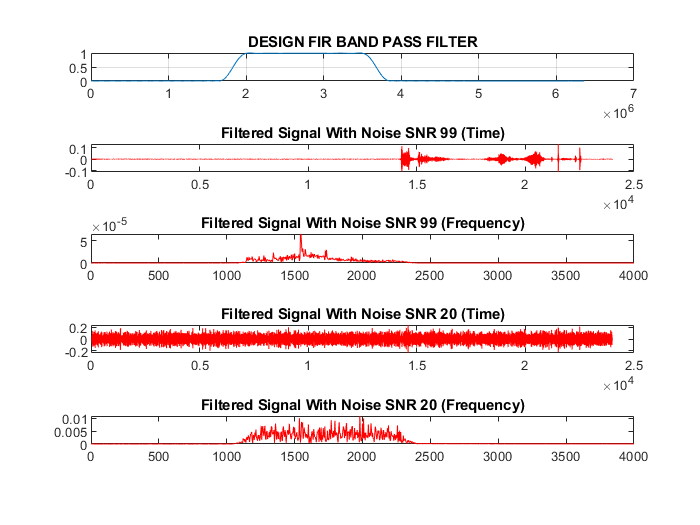

plot(f,2*abs(signal_6(1:NFFT/2+1)),'r');
title('Filtered Signal With Noise SNR 20 (Frequency)');


figure
z=signal_6

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


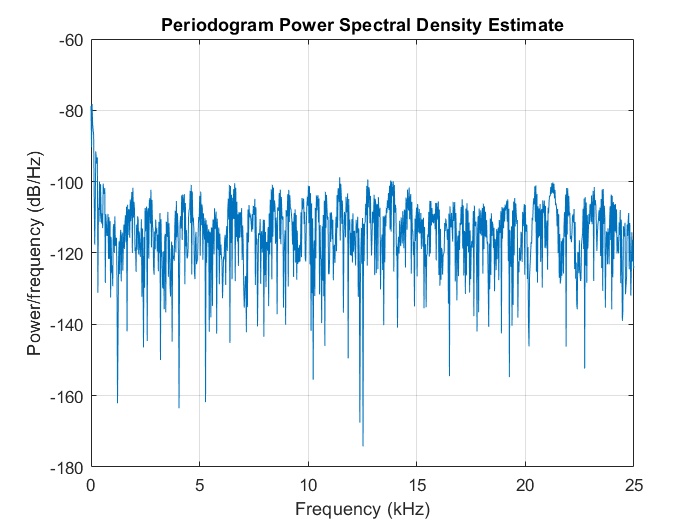

periodogram(gather(z),rectwin(length(z)),length(z),50e3)